
=== Distribución de Clases (Objetos Segmentados) ===


GlobuloBlanco   → 21146 objetos (10.76%)
Parasito        → 21719 objetos (11.05%)
Ruido           → 153708 objetos (78.19%)



⚠️  Clases potencialmente desbalanceadas (por debajo del 20%):


    {'GlobuloBlanco'}
    {'Parasito'     }



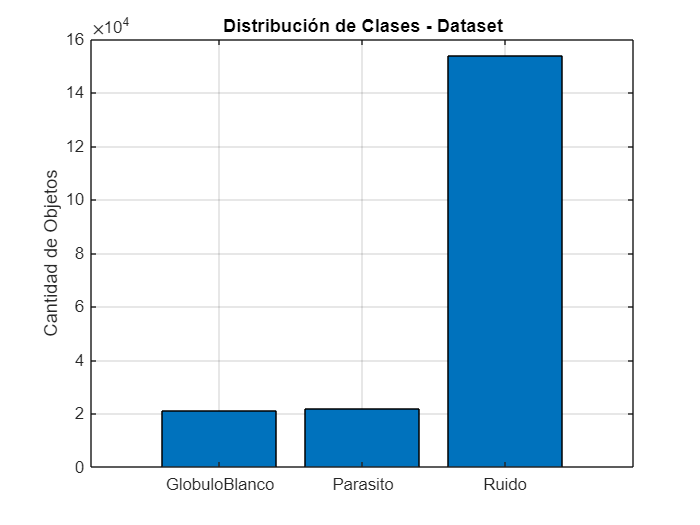

clear;close all;clc;

warning('off','all');

% Leer el dataset
T = readtable('dataset_global_thresholding.csv');
% Verificar existencia de columna 'Tipo'
if any(strcmp(T.Properties.VariableNames, 'Tipo'))
    % === Comprobación de desbalance de clases (antes de filtrar o modificar) ===
    fprintf('\n=== Distribución de Clases (Objetos Segmentados) ===\n');
    grupos_tipo = unique(T.Tipo);
    conteo = groupcounts(T.Tipo);
    porcentaje = 100 * conteo / sum(conteo);

    for i = 1:numel(grupos_tipo)
        fprintf('%-15s → %4d objetos (%.2f%%)\n', ...
            grupos_tipo{i}, conteo(i), porcentaje(i));
    end

    % Clases por debajo del 20%
    umbral = 20;
    clases_desbalanceadas = grupos_tipo(porcentaje < umbral);
    if ~isempty(clases_desbalanceadas)
        fprintf('\n⚠️  Clases potencialmente desbalanceadas (por debajo del %.0f%%):\n', umbral);
        disp(clases_desbalanceadas);
    end

    % === Gráfico ===
    figure;
    bar(categorical(grupos_tipo), conteo);
    ylabel('Cantidad de Objetos');
    title('Distribución de Clases - Dataset');
    grid on;
else
    warning('La variable "Tipo" no está presente en la tabla.');
end


% Eliminar primera columna si es 'NombreImagen'
if strcmp(T.Properties.VariableNames{1}, 'NombreImagen')
    T(:,1) = [];
end

% Definir tipos de interés
tipos_interes = {'GlobuloBlanco', 'Parasito', 'Ruido'};

% Filtrar solo los tipos de interés
T = T(ismember(T.Tipo, tipos_interes), :);

% Obtener variables numéricas (excepto Tipo)
numericVars = varfun(@isnumeric, T, 'OutputFormat', 'uniform');
varNames = T.Properties.VariableNames;
numericVarNames = varNames(numericVars);
numericVarNames(strcmp(numericVarNames, 'Tipo')) = [];
groups = unique(T.Tipo);

## Valores que faltan 

fprintf('Missing values por variable:\n\n');

Missing values por variable:



N = height(T);

for i = 1:width(T)
    varname = T.Properties.VariableNames{i};
    missing_count = sum(ismissing(T.(varname)));
    fprintf('%-20s → %3d missing (%.2f%%)\n', ...
        varname, missing_count, 100 * missing_count / N);
end

Tipo                 →   0 missing (0.00%)
Area                 →   0 missing (0.00%)
Perimetro            →   0 missing (0.00%)
Circularidad         →   0 missing (0.00%)
IntensidadR          →   0 missing (0.00%)
IntensidadG          →   0 missing (0.00%)
IntensidadB          →   0 missing (0.00%)
IntensidadRGBMedia   →   0 missing (0.00%)


## Comprobacion estadistica y outliers

for g = 1:length(groups)
    tipo = groups{g};
    fprintf('\n===== Tipo: %s =====\n', tipo);

    % Filtrar por grupo
    subset = T(strcmp(T.Tipo, tipo), :);
    nGroup = height(subset);

    % Análisis por variable
    for i = 1:length(numericVarNames)
        var = numericVarNames{i};
        x = subset.(var);

        % Calcular estadísticas
        missing_rate = sum(ismissing(x)) / nGroup * 100;
        m = mean(x, 'omitnan');
        med = median(x, 'omitnan');
        s = std(x, 'omitnan');
        mn = min(x);
        mx = max(x);

        % Mostrar resultados
        fprintf('Variable: %-20s Missing: %5.2f%% | Mean: %8.2f | Median: %8.2f | Std: %8.2f | Min: %8.2f | Max: %8.2f\n', ...
                var, missing_rate, m, med, s, mn, mx);
    end
end


===== Tipo: GlobuloBlanco =====


Variable: Area                 Missing:  0.00% | Mean:  6141.56 | Median:  4990.50 | Std:  5660.11 | Min:  1800.00 | Max: 207597.00
Variable: Perimetro            Missing:  0.00% | Mean:   490.16 | Median:   379.36 | Std:   371.37 | Min:   156.75 | Max: 11681.50
Variable: Circularidad         Missing:  0.00% | Mean:     0.46 | Median:     0.42 | Std:     0.28 | Min:     0.01 | Max:     1.02
Variable: IntensidadR          Missing:  0.00% | Mean:   119.81 | Median:   120.13 | Std:    55.76 | Min:     1.89 | Max:   222.71
Variable: IntensidadG          Missing:  0.00% | Mean:    71.80 | Median:    58.28 | Std:    52.27 | Min:     0.16 | Max:   204.30
Variable: IntensidadB          Missing:  0.00% | Mean:   181.76 | Median:   183.44 | Std:    24.83 | Min:    44.90 | Max:   227.80
Variable: IntensidadRGBMedia   Missing:  0.00% | Mean:   124.45 | Median:   120.40 | Std:    42.06 | Min:    23.34 | Max:   212.22



===== Tipo: Parasito =====


Variable: Area                 Missing:  0.00% | Mean:    58.82 | Median:    39.00 | Std:    67.70 | Min:     1.00 | Max:   400.00
Variable: Perimetro            Missing:  0.00% | Mean:    23.86 | Median:    20.51 | Std:    18.53 | Min:     0.00 | Max:   175.25
Variable: Circularidad         Missing:  0.00% | Mean:     1.30 | Median:     1.16 | Std:     1.07 | Min:     0.00 | Max:     6.54
Variable: IntensidadR          Missing:  0.00% | Mean:   146.82 | Median:   147.02 | Std:    13.87 | Min:    70.44 | Max:   204.04
Variable: IntensidadG          Missing:  0.00% | Mean:    70.27 | Median:    67.00 | Std:    26.50 | Min:    14.83 | Max:   177.00
Variable: IntensidadB          Missing:  0.00% | Mean:   177.05 | Median:   176.49 | Std:    13.97 | Min:    88.17 | Max:   225.73
Variable: IntensidadRGBMedia   Missing:  0.00% | Mean:   131.38 | Median:   129.88 | Std:    12.15 | Min:    77.83 | Max:   182.33



===== Tipo: Ruido =====


Variable: Area                 Missing:  0.00% | Mean:    33.57 | Median:     5.00 | Std:    66.92 | Min:     1.00 | Max:   400.00
Variable: Perimetro            Missing:  0.00% | Mean:    15.15 | Median:     5.88 | Std:    21.57 | Min:     0.00 | Max:   280.13
Variable: Circularidad         Missing:  0.00% | Mean:     1.70 | Median:     0.95 | Std:     2.00 | Min:     0.00 | Max:     6.54
Variable: IntensidadR          Missing:  0.00% | Mean:   152.62 | Median:   151.00 | Std:    15.86 | Min:    37.00 | Max:   215.10
Variable: IntensidadG          Missing:  0.00% | Mean:   100.82 | Median:    97.18 | Std:    28.19 | Min:    12.00 | Max:   192.00
Variable: IntensidadB          Missing:  0.00% | Mean:   194.51 | Median:   196.65 | Std:    14.47 | Min:    17.00 | Max:   249.00
Variable: IntensidadRGBMedia   Missing:  0.00% | Mean:   149.32 | Median:   150.33 | Std:    11.43 | Min:    22.67 | Max:   196.17


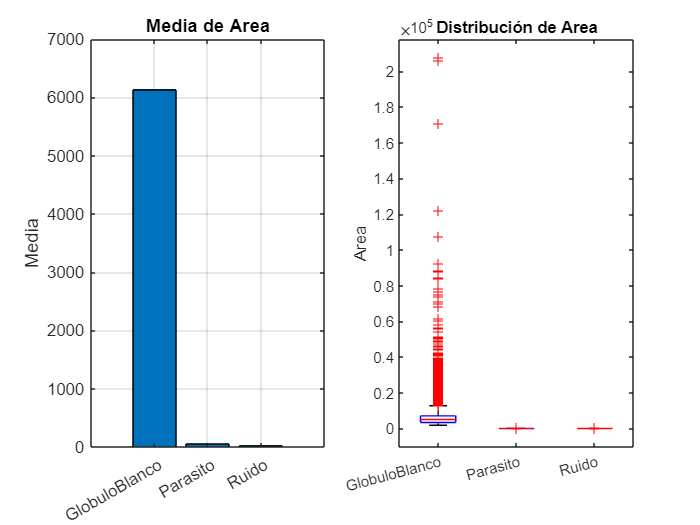

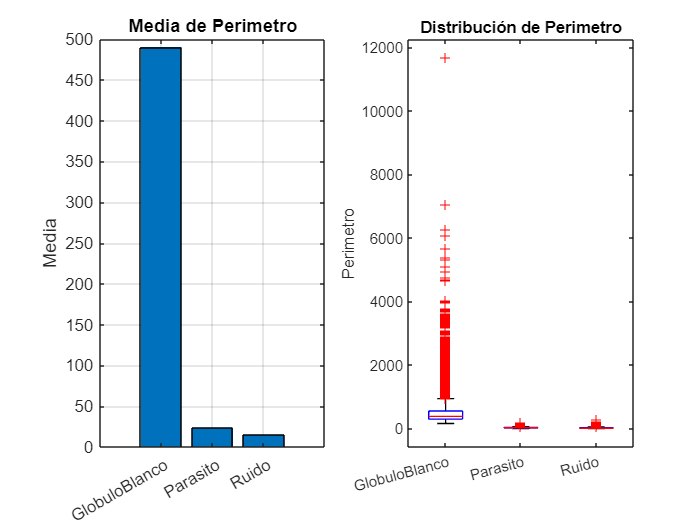

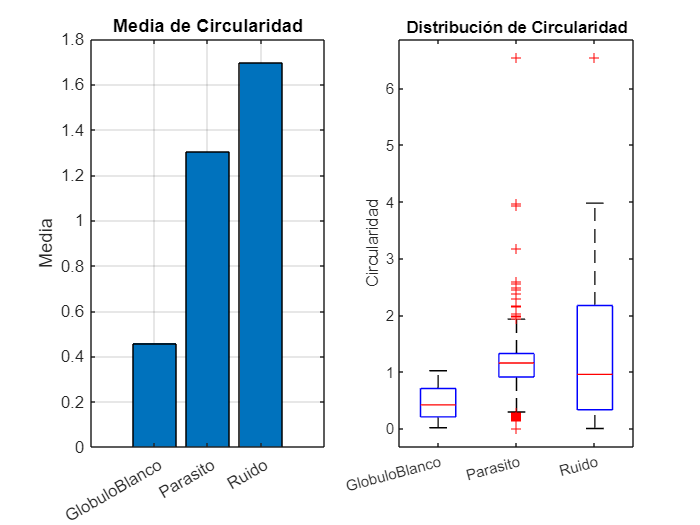

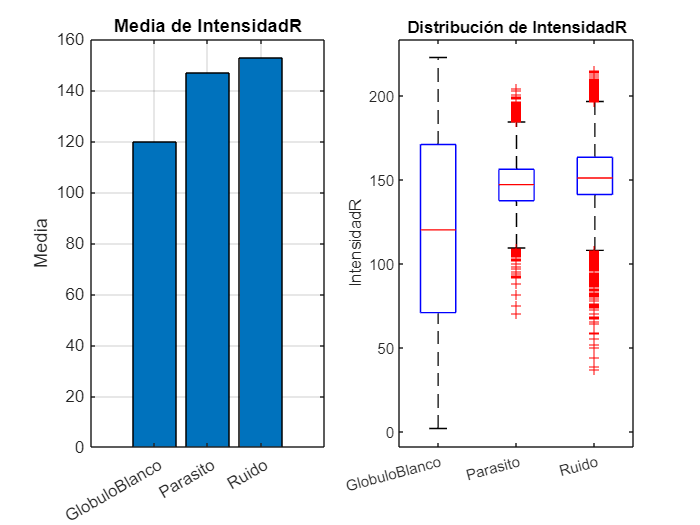

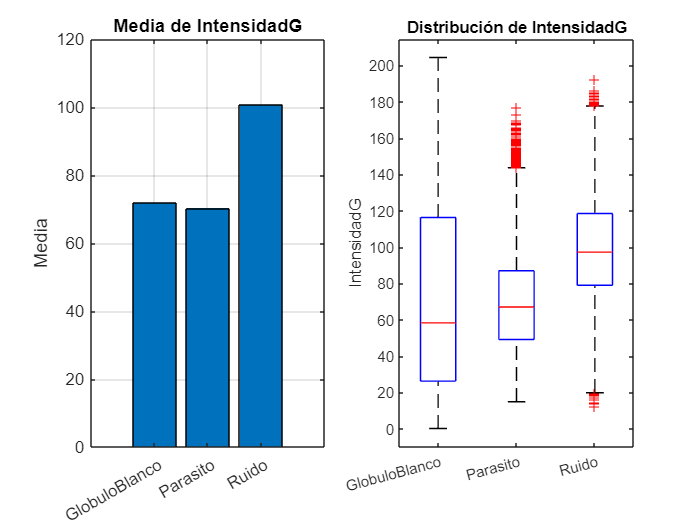

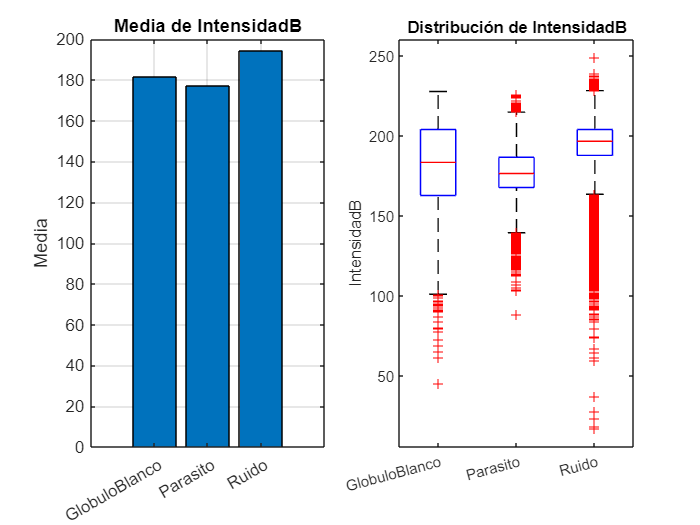

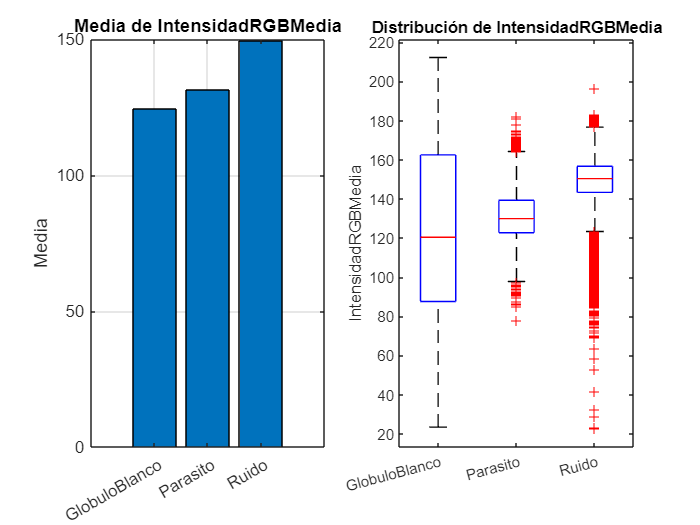


% Crear una figura por cada variable numérica

for j = 1:length(numericVarNames)
    var = numericVarNames{j};
    
    % Calcular medias
    medias = zeros(1, length(tipos_interes));
    for i = 1:length(tipos_interes)
        subset = T(strcmp(T.Tipo, tipos_interes{i}), :);
        medias(i) = mean(subset.(var), 'omitnan');
    end
    
    % Crear figura con 2 subplots: barra + boxplot
    figure('Name', var, 'NumberTitle', 'off');
    
    % Subplot 1: Gráfico de barras
    subplot(1,2,1);
    bar(medias);
    set(gca, 'XTickLabel', tipos_interes, 'FontSize', 10);
    title(['Media de ', var], 'Interpreter', 'none');
    ylabel('Media');
    grid on;

    % Subplot 2: Boxplot
    subplot(1,2,2);
    boxplot(T.(var), T.Tipo);
    title(['Distribución de ', var], 'Interpreter', 'none');
    ylabel(var, 'Interpreter', 'none');
    set(gca, 'XTickLabelRotation', 15);
end

## Correlación 

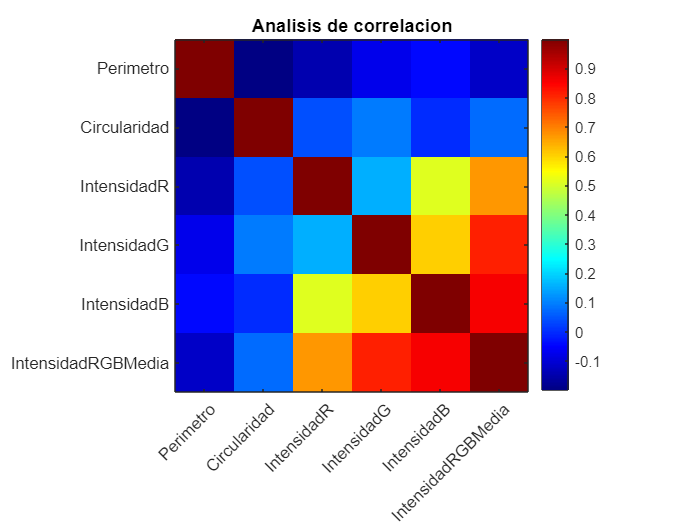

T(:,1:2) = [];

% Convertir a matriz numérica
datos = table2array(T);

% Calcular matriz de correlación (Pearson), considerando posibles NaNs
R = corrcoef(datos, 'Rows', 'pairwise');

% Visualizar la matriz de correlación
figure;
imagesc(R);                  
colormap(jet);              
colorbar;                   
title('Analisis de correlacion');
axis square;
xticks(1:size(R,1));
yticks(1:size(R,2));
xticklabels(T.Properties.VariableNames);
yticklabels(T.Properties.VariableNames);
xtickangle(45);


% Imprimir pares de variables altamente correlacionadas (> 0.9, sin diagonal)
high_correlations = abs(R) > 0.9;
[row, col] = find(triu(high_correlations, 1));  % solo parte superior para evitar duplicados

for i = 1:length(row)
    fprintf("Vars nº %d and nº %d, corresponding to %s and %s, are highly correlated\n", ...
        row(i), col(i), T.Properties.VariableNames{row(i)}, T.Properties.VariableNames{col(i)});
end


## Comprobar duplicados

% Detectar variables duplicadas: correlación absoluta igual a 1 (pero no consigo misma)
duplicadas = abs(R) == 1;
[row_dup, col_dup] = find(triu(duplicadas, 1));  % Solo parte superior (evita duplicados)

fprintf('\n--- Variables duplicadas por correlación perfecta ---\n');


--- Variables duplicadas por correlación perfecta ---


if isempty(row_dup)
    fprintf('No se encontraron variables duplicadas.\n');
else
    for i = 1:length(row_dup)
        fprintf("Duplicadas: %s y %s (índices %d y %d)\n", ...
            T.Properties.VariableNames{row_dup(i)}, ...
            T.Properties.VariableNames{col_dup(i)}, ...
            row_dup(i), col_dup(i));
    end
end

No se encontraron variables duplicadas.


## Annova 

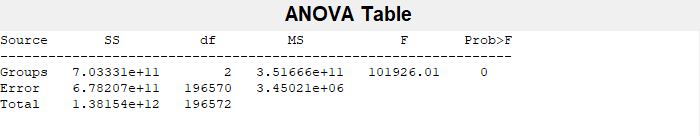

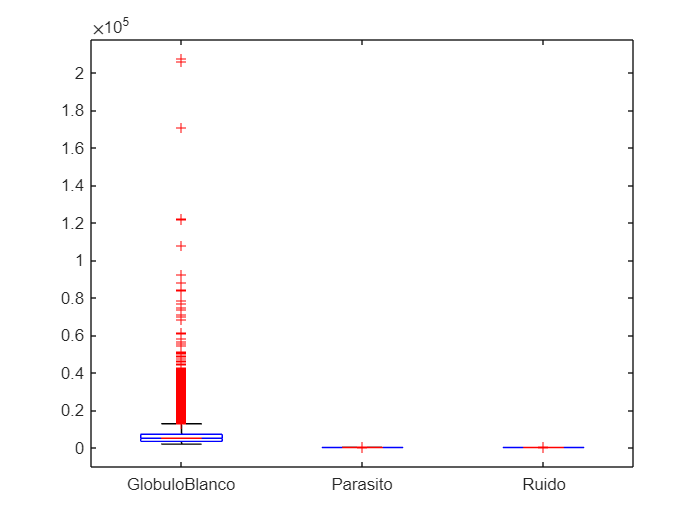

T = readtable('dataset_global_thresholding.csv');
variable = 'Area';  % Cambia por cualquier otra, como 'Circularidad', etc.

% Extraer datos y etiquetas
X = T.(variable);
grupos = T.Tipo;  % Clases: GlóbuloBlanco, Parasito, Ruido

% ANOVA de un factor
[p, tbl, stats] = anova1(X, grupos);


% Mostrar tabla de resultados
disp('Resultado del ANOVA:');

Resultado del ANOVA:


fprintf('p-valor: %.4f\n', p);

p-valor: 0.0000


if p < 0.05
    fprintf('Resultado estadísticamente significativo (p = %.4f < 0.05)\n', p);
else
    fprintf('Resultado NO estadísticamente significativo (p = %.4f ≥ 0.05)\n', p);
end

Resultado estadísticamente significativo (p = 0.0000 < 0.05)



% Opcional: prueba post-hoc (comparaciones múltiples)
disp('Post-hoc (comparaciones múltiples):');

Post-hoc (comparaciones múltiples):


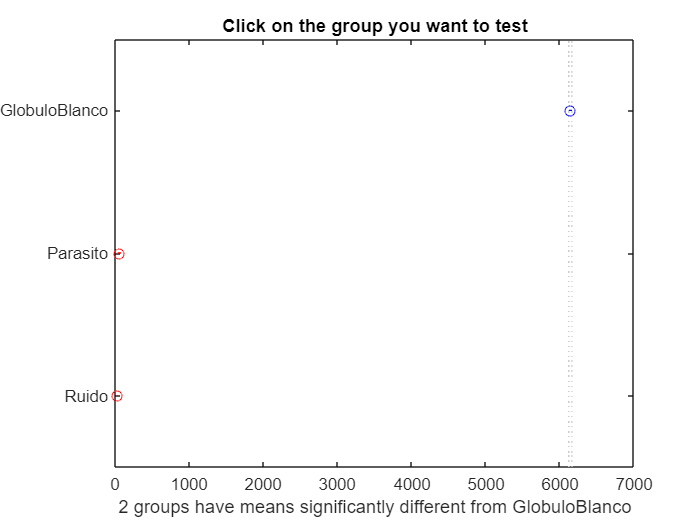

resultados_multicomparacion = multcompare(stats);

## Modelos de machine learning 

% === Cargar datos ===

T = readtable('dataset_global_thresholding.csv');
imagenes = unique(T.NombreImagen);
n = length(imagenes);

% === Contar objetos por clase ===
resultados = table();
resultados.NombreImagen = imagenes;
resultados.GlobuloBlanco = zeros(n,1);
resultados.Parasito = zeros(n,1);
resultados.Ruido = zeros(n,1);

for i = 1:n
    objetos = T(strcmp(T.NombreImagen, imagenes{i}), :);
    resultados.GlobuloBlanco(i) = sum(strcmp(objetos.Tipo, 'GlobuloBlanco'));
    resultados.Parasito(i) = sum(strcmp(objetos.Tipo, 'Parasito'));
    resultados.Ruido(i) = sum(strcmp(objetos.Tipo, 'Ruido'));
end

% === Etiqueta de clase dominante ===
[~, idx] = max([resultados.GlobuloBlanco, resultados.Parasito, resultados.Ruido], [], 2);
clases = {'GlobuloBlanco', 'Parasito', 'Ruido'};
resultados.Clase = categorical(clases(idx))';

% === Calcular características ===
vars = T.Properties.VariableNames(3:end);
medias = varfun(@mean, T, 'InputVariables', vars, 'GroupingVariables', 'NombreImagen');
X_table = normalize(medias{:, 2:end});
X = array2table(X_table, 'VariableNames', medias.Properties.VariableNames(2:end));
y = resultados.Clase;

% === Validación cruzada ===
k = 5;
cv = cvpartition(y, 'KFold', k);

% Inicializar acumuladores
model_names = {'Árbol de Decisión', 'Random Forest', 'KNN'};
y_true_all = [];
y_pred_all = cell(3,1);
models_all = cell(3,1);
scores_all = cell(3,1);

for fold = 1:k
    fprintf('\n=== Fold %d/%d ===\n', fold, k);

    X_train = X(training(cv, fold), :);
    y_train = y(training(cv, fold));
    X_test = X(test(cv, fold), :);
    y_test = y(test(cv, fold));
    y_true_all = [y_true_all; y_test];

    % Árbol de Decisión
    modelo_tree = fitctree(X_train, y_train, 'MaxNumSplits', 20);
    [y_pred_tree, scores_tree] = predict(modelo_tree, X_test);
    y_pred_all{1} = [y_pred_all{1}; y_pred_tree];
    scores_all{1} = [scores_all{1}; scores_tree];

    % Random Forest
    modelo_rf = TreeBagger(100, X_train, y_train, 'Method', 'classification', ...
        'PredictorNames', X.Properties.VariableNames, 'ResponseName', 'Clase');
    [y_pred_rf_cell, scores_rf] = predict(modelo_rf, X_test);
    y_pred_rf = categorical(y_pred_rf_cell);
    y_pred_all{2} = [y_pred_all{2}; y_pred_rf];
    scores_all{2} = [scores_all{2}; scores_rf];

    % KNN
    modelo_knn = fitcknn(X_train, y_train, 'NumNeighbors', 5);
    [y_pred_knn, scores_knn] = predict(modelo_knn, X_test);
    y_pred_all{3} = [y_pred_all{3}; y_pred_knn];
    scores_all{3} = [scores_all{3}; scores_knn];
end


=== Fold 1/5 ===

=== Fold 2/5 ===

=== Fold 3/5 ===

=== Fold 4/5 ===

=== Fold 5/5 ===


Árbol de Decisión:


Accuracy: 87.46%
GlobuloBlanco - Precisión: 82.05%, Sensibilidad (Recall): 84.21%
Parasito - Precisión: 62.30%, Sensibilidad (Recall): 55.07%
Ruido - Precisión: 92.26%, Sensibilidad (Recall): 93.29%


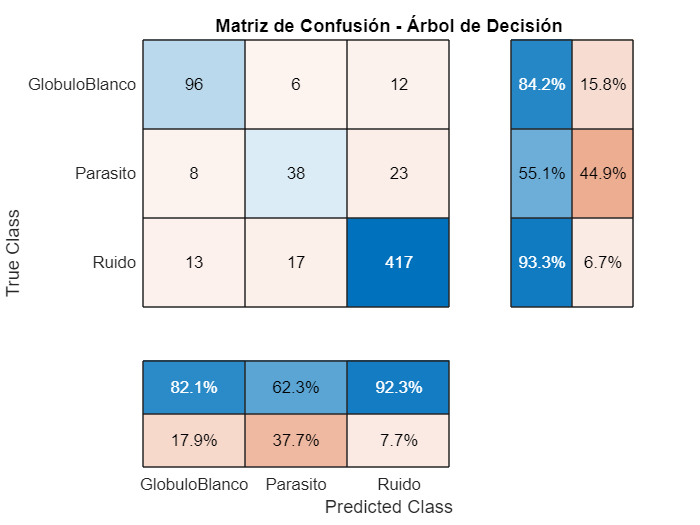

Random Forest:


Accuracy: 90.48%
GlobuloBlanco - Precisión: 85.95%, Sensibilidad (Recall): 91.23%
Parasito - Precisión: 80.00%, Sensibilidad (Recall): 57.97%
Ruido - Precisión: 92.81%, Sensibilidad (Recall): 95.30%


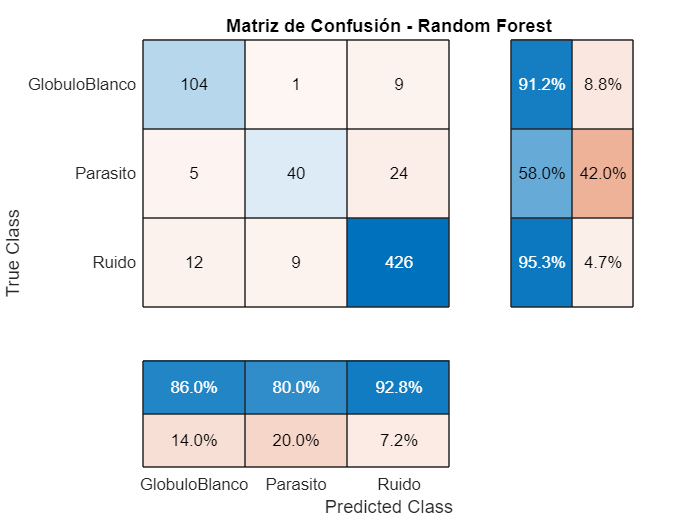

KNN:


Accuracy: 87.78%
GlobuloBlanco - Precisión: 83.76%, Sensibilidad (Recall): 85.96%
Parasito - Precisión: 65.67%, Sensibilidad (Recall): 63.77%
Ruido - Precisión: 92.15%, Sensibilidad (Recall): 91.95%


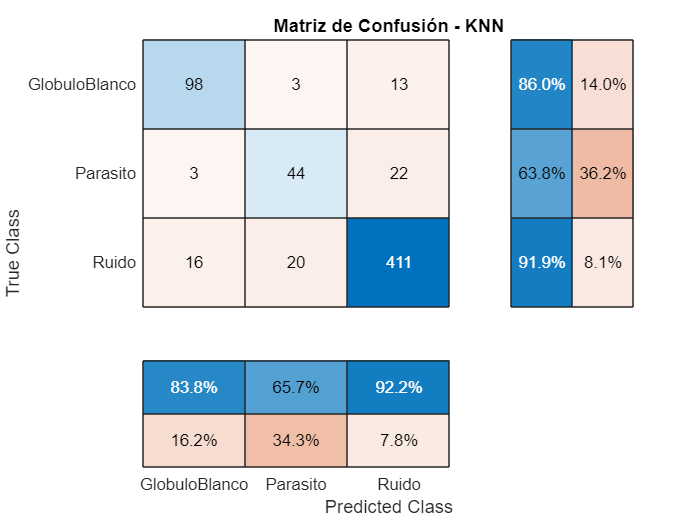


save('modelo_random_forest.mat','modelo_rf');

% Evaluación final
for m = 1:3
    fprintf('\n%s:\n', model_names{m});
    evaluate_model(y_true_all, y_pred_all{m}, clases, model_names{m});
end

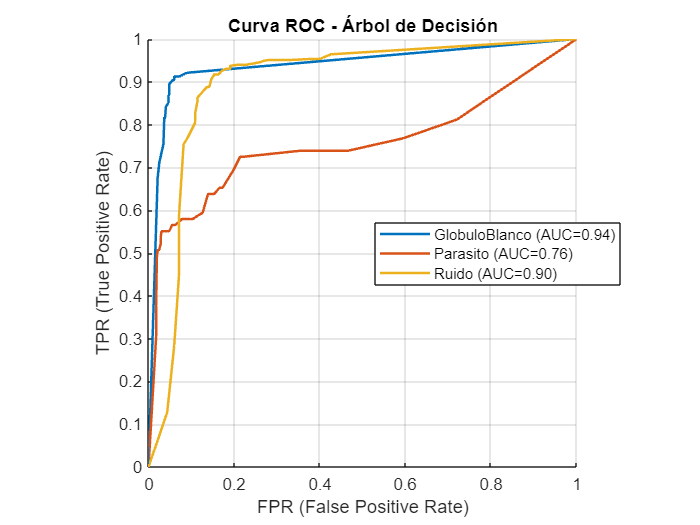

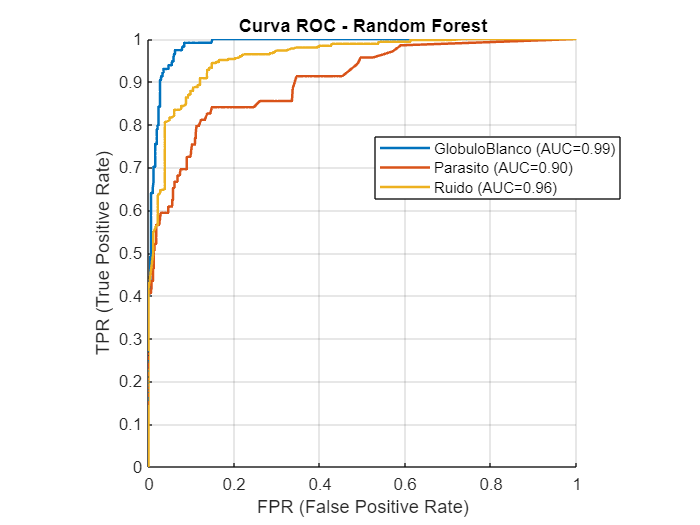

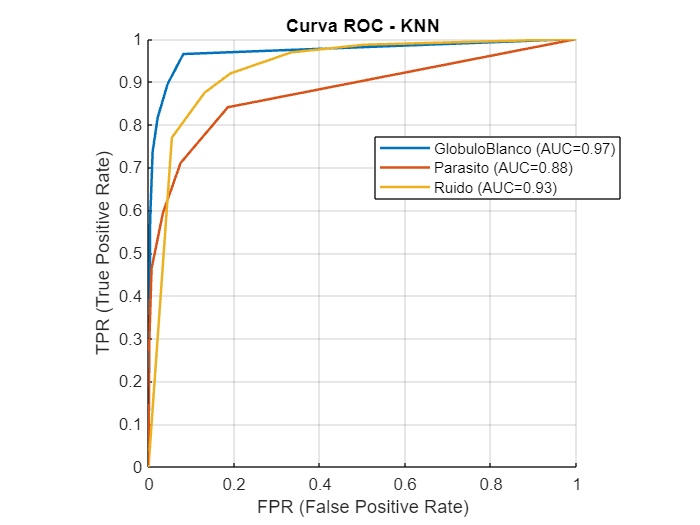


% Curvas ROC finales
for m = 1:3
    figure;
    hold on;
    title(['Curva ROC - ', model_names{m}], 'FontWeight', 'bold');
    xlabel('FPR (False Positive Rate)');
    ylabel('TPR (True Positive Rate)');

    % Etiquetas binarizadas
    y_bin = zeros(length(y_true_all), length(clases));
    for c = 1:length(clases)
        y_bin(:,c) = (y_true_all == clases{c});
    end

    scores = scores_all{m};

    for c = 1:length(clases)
        if size(scores,2) < c
            continue;
        end
        [Xroc, Yroc, ~, AUC] = perfcurve(y_bin(:,c), scores(:,c), 1);
        plot(Xroc, Yroc, 'LineWidth', 1.5, 'DisplayName', ...
            [clases{c}, ' (AUC=', num2str(AUC, '%.2f'), ')']);
    end
    legend('show', 'Location', 'best');
    grid on; axis square;
end

% === IMPORTANCIA DE VARIABLES CON RANDOM FOREST ===
modelo_rf_full = TreeBagger(50, X, y, 'Method', 'classification','OOBPredictorImportance', 'on', 'PredictorNames', X.Properties.VariableNames,'ResponseName', 'Clase');

importance = modelo_rf_full.OOBPermutedPredictorDeltaError;

% Ordenar e imprimir
[sortedImp, idxImp] = sort(importance, 'descend');
fprintf('\n=== Importancia de características (Random Forest) ===\n');


=== Importancia de características (Random Forest) ===


for i = 1:length(idxImp)
    fprintf('%2d. %s: %.4f\n', i, X.Properties.VariableNames{idxImp(i)}, sortedImp(i));
end

 1. mean_Perimetro: 1.6381
 2. mean_Circularidad: 1.4505
 3. mean_IntensidadG: 1.2856
 4. mean_Area: 1.2522
 5. mean_IntensidadRGBMedia: 1.1966
 6. GroupCount: 0.9443
 7. mean_IntensidadB: 0.9331
 8. mean_IntensidadR: 0.6356


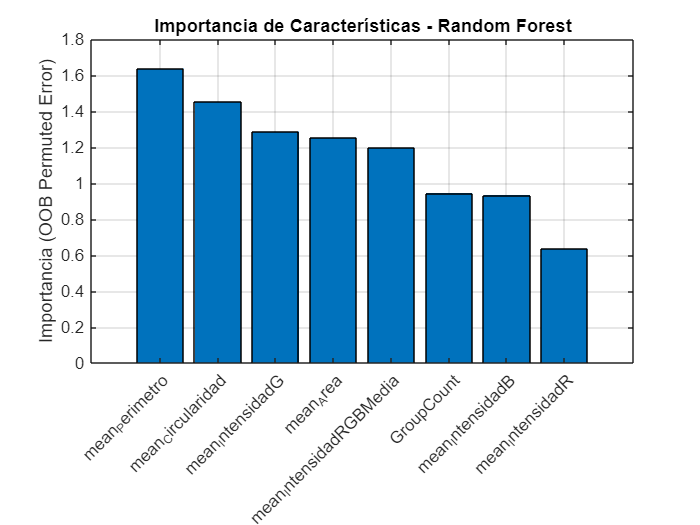


% Gráfico de importancia
figure;
bar(importance(idxImp));
xticklabels(X.Properties.VariableNames(idxImp));
xtickangle(45);
ylabel('Importancia (OOB Permuted Error)');
title('Importancia de Características - Random Forest');
grid on;

function evaluate_model(y_true, y_pred, clases, model_name)
    fprintf('Accuracy: %.2f%%\n', 100 * mean(y_true == y_pred));

    for i = 1:length(clases)
        class = clases{i};
        TP = sum((y_true == class) & (y_pred == class));
        FP = sum((y_true ~= class) & (y_pred == class));
        FN = sum((y_true == class) & (y_pred ~= class));
        precision = TP / (TP + FP + eps);
        recall = TP / (TP + FN + eps);
        fprintf('%s - Precisión: %.2f%%, Sensibilidad (Recall): %.2f%%\n', ...
            class, 100 * precision, 100 * recall);
    end

    figure;
    confusionchart(y_true, y_pred, ...
        'Title', ['Matriz de Confusión - ' model_name], ...
        'RowSummary', 'row-normalized', ...
        'ColumnSummary', 'column-normalized');
end